### Fig 5a

clear; clc;

% ===== Parameters =====
K = 1;             
Omega = 50;         
alpha = 2;
delta = 0.04;       
P0_fixed = 0.1;     


num_r = 20;
num_a = 20;
r_vec = linspace(0.1, 1.9, num_r);       
a_vec = logspace(log10(0.02), log10(0.2), num_a);  


grid_size = 100;
B0_vec = logspace(-2, log10(0.5), grid_size);  % B0: 0.01 ~ 0.5
I0_vec = logspace(-2, log10(0.5), grid_size);  % I0: 0.01 ~ 0.5
total_points = grid_size^2;


t_final = 500;
extinct_thres = 1e-8;


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
tspan = [0, t_final];


survival_ratio_map = zeros(num_r, num_a);


fprintf('Starting 20x20 parameter scan...\n');

Starting 20x20 parameter scan...


for r_idx = 1:num_r
    r = r_vec(r_idx);
    fprintf('Processing r = %.3f (%d/%d)\n', r, r_idx, num_r);
    
    for a_idx = 1:num_a
        a = a_vec(a_idx);
        
  
        state_matrix = zeros(grid_size, grid_size);

        parfor i = 1:grid_size
            for j = 1:grid_size
                B0 = B0_vec(j);
                I0 = I0_vec(i);
                y0 = [B0; I0; P0_fixed];
                
                [~, y] = ode15s(@(t,y) ode1B(t, y, r, K, a, Omega, alpha, delta), ...
                                tspan, y0, options);
                
 
                n = size(y, 1);
                last_y_B = y(floor(n*0.9):end, 1);
                

                if min(last_y_B) >= extinct_thres
                    state_matrix(i, j) = 1;
                else
                    state_matrix(i, j) = 0; 
                end
            end
        end
        

        survival_ratio_map(r_idx, a_idx) = sum(state_matrix(:)) / total_points;

        if mod(a_idx, ceil(num_a/10)) == 0 || a_idx == num_a
            fprintf('  -> a = %.4f, survival = %.3f\n', a, survival_ratio_map(r_idx, a_idx));
        end
    end
end

Processing r = 0.100 (1/20)


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


  -> a = 0.0226, survival = 0.997
  -> a = 0.0288, survival = 0.971
  -> a = 0.0367, survival = 0.868
  -> a = 0.0467, survival = 0.741
  -> a = 0.0595, survival = 0.627
  -> a = 0.0759, survival = 0.505
  -> a = 0.0967, survival = 0.400
  -> a = 0.1232, survival = 0.308
  -> a = 0.1570, survival = 0.213
  -> a = 0.2000, survival = 0.136


Processing r = 0.195 (2/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.990
  -> a = 0.0367, survival = 0.908
  -> a = 0.0467, survival = 0.788
  -> a = 0.0595, survival = 0.664
  -> a = 0.0759, survival = 0.523
  -> a = 0.0967, survival = 0.368
  -> a = 0.1232, survival = 0.261
  -> a = 0.1570, survival = 0.181
  -> a = 0.2000, survival = 0.118


Processing r = 0.289 (3/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 0.998
  -> a = 0.0367, survival = 0.914
  -> a = 0.0467, survival = 0.801
  -> a = 0.0595, survival = 0.674
  -> a = 0.0759, survival = 0.496
  -> a = 0.0967, survival = 0.301
  -> a = 0.1232, survival = 0.194
  -> a = 0.1570, survival = 0.125
  -> a = 0.2000, survival = 0.066


Processing r = 0.384 (4/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.907
  -> a = 0.0467, survival = 0.773
  -> a = 0.0595, survival = 0.647
  -> a = 0.0759, survival = 0.415
  -> a = 0.0967, survival = 0.203
  -> a = 0.1232, survival = 0.113
  -> a = 0.1570, survival = 0.053
  -> a = 0.2000, survival = 0.015


Processing r = 0.479 (5/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.892
  -> a = 0.0467, survival = 0.680
  -> a = 0.0595, survival = 0.567
  -> a = 0.0759, survival = 0.354
  -> a = 0.0967, survival = 0.151
  -> a = 0.1232, survival = 0.066
  -> a = 0.1570, survival = 0.020
  -> a = 0.2000, survival = 0.001


Processing r = 0.574 (6/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.854
  -> a = 0.0467, survival = 0.608
  -> a = 0.0595, survival = 0.504
  -> a = 0.0759, survival = 0.342
  -> a = 0.0967, survival = 0.119
  -> a = 0.1232, survival = 0.037
  -> a = 0.1570, survival = 0.005
  -> a = 0.2000, survival = 0.000


Processing r = 0.668 (7/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.836
  -> a = 0.0467, survival = 0.556
  -> a = 0.0595, survival = 0.455
  -> a = 0.0759, survival = 0.336
  -> a = 0.0967, survival = 0.090
  -> a = 0.1232, survival = 0.020
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 0.763 (8/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.857
  -> a = 0.0467, survival = 0.516
  -> a = 0.0595, survival = 0.416
  -> a = 0.0759, survival = 0.354
  -> a = 0.0967, survival = 0.068
  -> a = 0.1232, survival = 0.009
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 0.858 (9/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 0.946
  -> a = 0.0467, survival = 0.487
  -> a = 0.0595, survival = 0.382
  -> a = 0.0759, survival = 0.326
  -> a = 0.0967, survival = 0.062
  -> a = 0.1232, survival = 0.004
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 0.953 (10/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.468
  -> a = 0.0595, survival = 0.353
  -> a = 0.0759, survival = 0.302
  -> a = 0.0967, survival = 0.052
  -> a = 0.1232, survival = 0.001
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.047 (11/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.457
  -> a = 0.0595, survival = 0.330
  -> a = 0.0759, survival = 0.280
  -> a = 0.0967, survival = 0.051
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.142 (12/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.454
  -> a = 0.0595, survival = 0.310
  -> a = 0.0759, survival = 0.260
  -> a = 0.0967, survival = 0.047
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.237 (13/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.461
  -> a = 0.0595, survival = 0.294
  -> a = 0.0759, survival = 0.242
  -> a = 0.0967, survival = 0.051
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.332 (14/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.486
  -> a = 0.0595, survival = 0.280
  -> a = 0.0759, survival = 0.227
  -> a = 0.0967, survival = 0.060
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.426 (15/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.530
  -> a = 0.0595, survival = 0.269
  -> a = 0.0759, survival = 0.212
  -> a = 0.0967, survival = 0.073
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.521 (16/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.650
  -> a = 0.0595, survival = 0.260
  -> a = 0.0759, survival = 0.200
  -> a = 0.0967, survival = 0.094
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.616 (17/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 0.912
  -> a = 0.0595, survival = 0.255
  -> a = 0.0759, survival = 0.190
  -> a = 0.0967, survival = 0.121
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.711 (18/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 1.000
  -> a = 0.0595, survival = 0.254
  -> a = 0.0759, survival = 0.179
  -> a = 0.0967, survival = 0.154
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.805 (19/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 1.000
  -> a = 0.0595, survival = 0.254
  -> a = 0.0759, survival = 0.169
  -> a = 0.0967, survival = 0.145
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


Processing r = 1.900 (20/20)


  -> a = 0.0226, survival = 1.000
  -> a = 0.0288, survival = 1.000
  -> a = 0.0367, survival = 1.000
  -> a = 0.0467, survival = 1.000
  -> a = 0.0595, survival = 0.251
  -> a = 0.0759, survival = 0.161
  -> a = 0.0967, survival = 0.137
  -> a = 0.1232, survival = 0.000
  -> a = 0.1570, survival = 0.000
  -> a = 0.2000, survival = 0.000


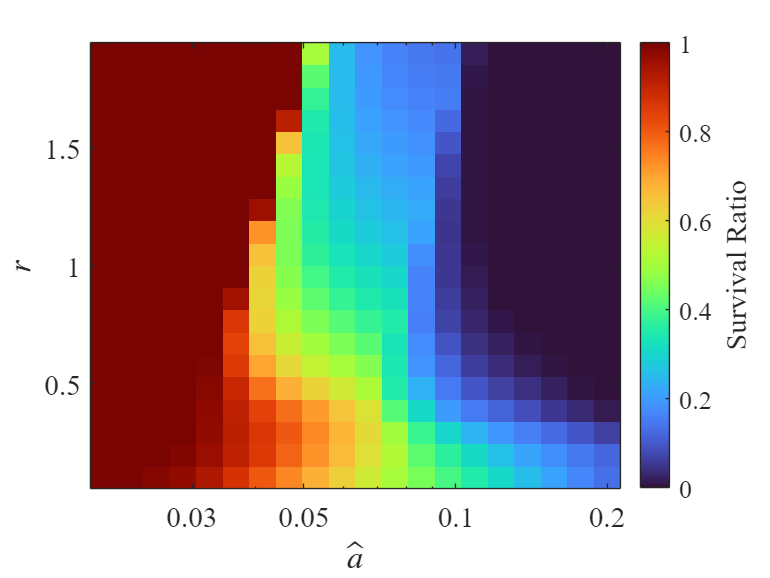

% ===== Visualization =====
figure;
imagesc(a_vec, r_vec, survival_ratio_map);
hcb = colorbar('Location','eastoutside');
colormap("turbo");

hcb.Label.String = 'Survival Ratio';
hcb.Label.FontSize = 16;
hcb.Label.FontName = 'Times New Roman';
xlabel('$\hat{a}$', 'Interpreter', 'latex', 'FontSize', 18, 'FontName', 'Times New Roman');
ylabel('$r$ ', 'Interpreter', 'latex', 'FontSize', 18, 'FontName', 'Times New Roman');
%title('Survival Ratio (Fraction of Initial Conditions Surviving)', 'FontSize', 20, 'FontName', 'Times New Roman');

ax = gca;
ax.XScale = 'log';
xticks([0.03, 0.05, 0.1, 0.2]);
set(ax, 'FontSize', 16, 'FontName', 'Times New Roman');


ylim([min(r_vec) max(r_vec)]);
set(gca, 'YDir', 'normal');


grid off;
box on;
axis tight;


% saveas(gcf, 'survival_heatmap.png');

### Fig 5h-k

clear; clc;

% ===== Parameters =====
K = 1;        
a = 0.07;       
Omega = 50;        
alpha = 2;
delta = 0.04;    

grid_size = 50;    


P0 = 0.1;  


B0_vec = logspace(-2, log10(0.5), grid_size);   % Susceptible bacteria
I0_vec = logspace(-2, log10(0.5), grid_size);   % Infected bacteria

t_final = 500;          
extinct_thres = 1e-8;   


r_values = [0.2, 0.6, 1.0, 1.4];


state_matrices = cell(1, length(r_values));


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
tspan = [0, t_final];

for r_idx = 1:length(r_values)
    r = r_values(r_idx);

    state_matrix = zeros(length(I0_vec), length(B0_vec));  

    fprintf('Processing r = %.2f\n', r);

    parfor i = 1:grid_size
        for j = 1:grid_size
            I0 = I0_vec(i);
            B0 = B0_vec(j);
            y0 = [B0; I0; P0]; 

            [~, y] = ode15s(@(t,y) ode1B(t, y, r, K, a, Omega, alpha, delta), ...
                            tspan, y0, options);

            n = size(y, 1);
            last_y_B = y(floor(n*0.9):end, 1);

            if min(last_y_B) >= extinct_thres
                state_matrix(i, j) = 1; 
            else
                state_matrix(i, j) = 0;  
            end
        end
    end

    state_matrices{r_idx} = state_matrix;
end

Processing r = 0.20


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


Processing r = 0.60
Processing r = 1.00
Processing r = 1.40


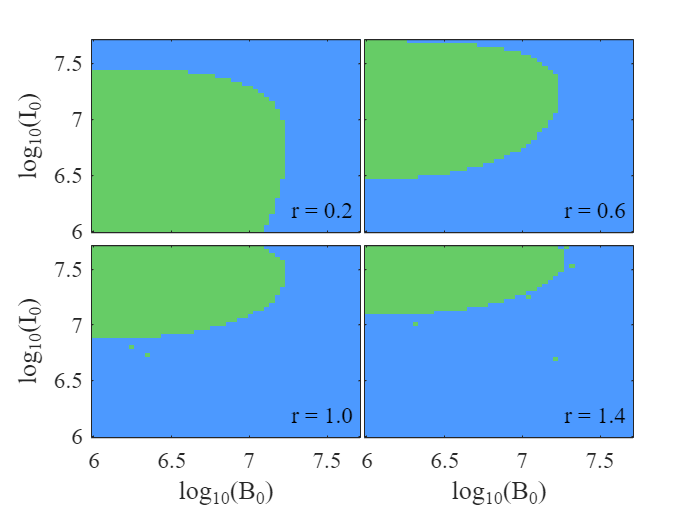

% ===== Visualization=====
figure;

fontSize = 14;
tl = tiledlayout(2, 2, 'TileSpacing', 'tight');

for r_idx = 1:length(r_values)
    ax = nexttile(tl);
    
    imagesc(ax, log10(B0_vec*10^8), log10(I0_vec*10^8), state_matrices{r_idx});
    set(ax, 'YDir', 'normal');

    colormap(ax, [0.3 0.6 1; 0.4 0.8 0.4]);  
    caxis(ax, [-0.5 1.5]);

    if r_idx == 3 || r_idx == 4
        xlabel(ax, 'log_{10}(B_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman')
    else
        ax.XTickLabel = [];  
    end

    if r_idx == 1 || r_idx == 3
        ylabel(ax, 'log_{10}(I_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
    else
        ax.YTickLabel = [];
    end
    

    xlim_val = get(ax, 'XLim');
    ylim_val = get(ax, 'YLim');
    

    text(ax, xlim_val(2) - 0.05, ylim_val(2) - 1.4, ...
         sprintf('r = %.1f', r_values(r_idx)), ...
         'FontSize', fontSize, 'FontName', 'Times New Roman', ...
         'FontWeight', 'normal', 'HorizontalAlignment', 'right', ...
         'VerticalAlignment', 'top');
    

    ax.FontName = 'Times New Roman';
    ax.FontSize = fontSize;
end

### Fig 5d-g

clear; clc;

% ===== Parameters =====
K = 1;             
a = 0.038;       
Omega = 50;       
alpha = 2;
delta = 0.04;       

grid_size = 50;    


P0 = 0.1; 


B0_vec = logspace(-2, log10(0.5), grid_size);   % Susceptible bacteria
I0_vec = logspace(-2, log10(0.5), grid_size);   % Infected bacteria

t_final = 500;          
extinct_thres = 1e-8;  


r_values = [0.2, 0.6, 1.0, 1.4];


state_matrices = cell(1, length(r_values));


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);
tspan = [0, t_final];


for r_idx = 1:length(r_values)
    r = r_values(r_idx);

    state_matrix = zeros(length(I0_vec), length(B0_vec));

    fprintf('Processing r = %.2f\n', r);

    parfor i = 1:grid_size
        for j = 1:grid_size
            I0 = I0_vec(i);
            B0 = B0_vec(j);
            y0 = [B0; I0; P0]; 

            [~, y] = ode15s(@(t,y) ode1B(t, y, r, K, a, Omega, alpha, delta), ...
                            tspan, y0, options);

            n = size(y, 1);
            last_y_B = y(floor(n*0.9):end, 1);  

            if min(last_y_B) >= extinct_thres
                state_matrix(i, j) = 1; 
            else
                state_matrix(i, j) = 0; 
            end
        end
    end

    state_matrices{r_idx} = state_matrix;
end

Processing r = 0.20
Processing r = 0.60
Processing r = 1.00
Processing r = 1.40


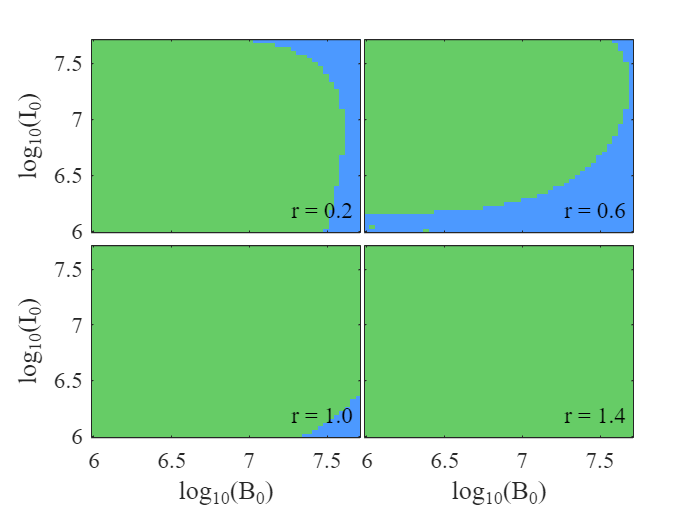

% ===== Visualization=====
figure;

fontSize = 14;
tl = tiledlayout(2, 2, 'TileSpacing', 'tight');

for r_idx = 1:length(r_values)
    ax = nexttile(tl);
    

    imagesc(ax, log10(B0_vec*10^8), log10(I0_vec*10^8), state_matrices{r_idx});
    set(ax, 'YDir', 'normal');

    colormap(ax, [0.3 0.6 1; 0.4 0.8 0.4]); 
    caxis(ax, [-0.5 1.5]);

    if r_idx == 3 || r_idx == 4
        xlabel(ax, 'log_{10}(B_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman')
    else
        ax.XTickLabel = []; 
    end
    

    if r_idx == 1 || r_idx == 3
        ylabel(ax, 'log_{10}(I_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
    else
        ax.YTickLabel = [];
    end

    xlim_val = get(ax, 'XLim');
    ylim_val = get(ax, 'YLim');

    text(ax, xlim_val(2) - 0.05, ylim_val(2) - 1.4, ...
         sprintf('r = %.1f', r_values(r_idx)), ...
         'FontSize', fontSize, 'FontName', 'Times New Roman', ...
         'FontWeight', 'normal', 'HorizontalAlignment', 'right', ...
         'VerticalAlignment', 'top');
    

    ax.FontName = 'Times New Roman';
    ax.FontSize = fontSize;
end

### Fig b-c

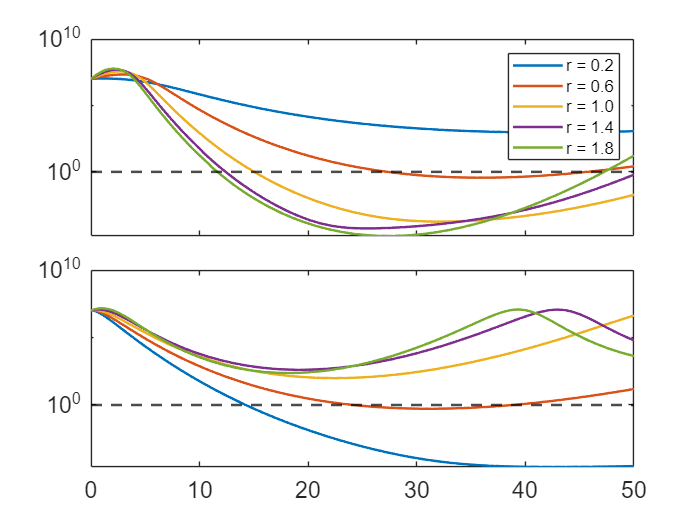

K = 1;              
a = 0.07;         
Omega = 50;        
alpha = 2;
delta = 0.04;       
r_values = [0.2, 0.6, 1.0, 1.4,1.8];

tspan = [0 50];

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12, 'MaxStep', 0.1);


figure;

tl = tiledlayout(2, 1, 'TileSpacing', 'tight'); 

B0_1 = 0.1;
I0_1 = 0.05;
P0_1 = 0.1;
y0_1 = [B0_1; I0_1; P0_1];


B0_2 = 0.1;
I0_2 = 0.4;
P0_2 = 0.1;
y0_2 = [B0_2; I0_2; P0_2];


colors = lines(length(r_values));

ax1 = nexttile;
hold(ax1, 'on');
for i = 1:length(r_values)
    r = r_values(i);
    [t, y] = ode15s(@(t,y) ode1B_nothre(t, y, r, K, a, Omega, alpha, delta), tspan, y0_1, options);
    y_scaled = y * 1e8;
    plot(ax1, t, y_scaled(:,1), '-', 'Color', colors(i,:), 'LineWidth', 1.5);
end


yline(ax1, 1, '--k', 'LineWidth', 1.5); 


ax1.YScale = 'log';
ax1.XTickLabel = {};
grid(ax1, 'off');
box(ax1, 'on');


ax1.FontSize = 14;


leg1 = legend(ax1, arrayfun(@(r)sprintf('r = %.1f', r), r_values, 'UniformOutput', false), 'Location', 'northeast');
leg1.FontSize = 10;
box(leg1,'on');


ax2 = nexttile;
hold(ax2, 'on');
for i = 1:length(r_values)
    r = r_values(i);
    [t, y] = ode15s(@(t,y) ode1B_nothre(t, y, r, K, a, Omega, alpha, delta), tspan, y0_2, options);
    y_scaled = y * 1e8;
    plot(ax2, t, y_scaled(:,1), '-', 'Color', colors(i,:), 'LineWidth', 1.5);
end


yline(ax2, 1, '--k', 'LineWidth', 1.5);


ax2.YScale = 'log';
grid(ax2, 'off');
box(ax2, 'on');


ax2.FontSize = 14;